## CSTR 

La reazione che avviene all'interno del CSTR è una reazione elementare in fase singola del tipo:


$$A \rightarrow B
$$


Definisco per questa reazione il rate of production($r$) come:


$$r=kc_A


$$


con $k
$ costante di reazione, questa è definita dalla relazione di Arrenius e ha una forte dipendenza dalla temperatura.


$$k=k_0 e^{-

\frac{E_{att}}{RT}}$$


Con $k_0
$ definito come il fattore di frequenza proporzionale al numero degli urti nella reazione, che moltiplica l'esponenziale di meno l'energia di attivazione($E_{att}$), divisa per la costante dei gas$(R)$ e la temperatura($T$).

#### Perfetta miscelazione

Per descrivere il reattore CSTR considero un sistema in condizioni di perfetta miscelazione, non saranno presenti quindi all'interno del Volume($V$) del reattore gradienti.

#### Densità costante

Per descirvere il reattore CSTR considero il fluido nel reattore a densità costante.

#### Volume di liquido costante

Il volume di liquido all'interno del reattore è mantenuto costante da una overflow line.

### Bilancio totale di materia nel sistema in condizioni non stazionarie


$$\frac{d(\rho V)}{dt}=\rho q_{in} -\rho q_{out}
$$


Per le condizioni di$V$e $\rho$ costanti, il bilancio di materia per un CSTR viene ridotto.


$$q_{in}=q_{out}$$


### Bilancio di materia per il composto A all'interno del sistema


$$V\frac{dc_A}{dt}=q_{in}(c_{A_{in}}-c_A)-Vkc_A$$


Questa definizione del bilancio di materia per il componente A nel sistema si ottiene applicando l'equazione per il bilancio totale di materia e la definizoine di rate of production, questa va introdotta nel bilancio previa moltiplicazione per il Volume del reattore in cui avviene la reazione, se questa è da considerarsi nel liquido, in caso di reazione superficiale o di reazione catalizzata, sarà necessario andare a definire il valore del rate of reaction per il caso specifico e andare a valutare il coefficiente specifico da moltiplicare, ottenuto tramite il rapporto dell'area di reazione con il volume del reattore.

#### Considerazioni Termiche per il bilancio di energia

Considero il calore scambiato con l'esterno dal sistema eliminabile data la presenza di una reazione all'interno del reattore nel caso in cui questa sia fortemente esoT o endoT.

Considero gli organi di raffreddamento a $T_c
$ costante.

La potenza scambiata dal raffreddamento del sistema può essere definita con l'utilizzo di un coefficiente di scambio termico globale che racchiude, convezione forzata lato reattore e mantello e conduzione all'interno del materiale di cui il reattore è composto.


$$Q=UA(T_c-T)$$


La variazione di entalpia per la miscela nel reattore dovuta alla miscelazione è eliminabile considerando l'entità della variazione dovuta alla reazione in atto.

Infine il lavoro all'albero($W_s$) e il calore scambiato con l'ambiente esterno($Q_{amb}$) sono considerabili eliminabili.

### Bilancio di energia per CSTR con reazione elementare 

Considerando le ipotesi descritte in precedenza si può ottenere la reazione del bilancio di energia per il reattore.


$$V\rho C \frac{dT}{dt}=w C (T_i -T)+(-\Delta H_{R})Vkc_A +UA(T_c-T)$$


Dove $T_i$ rapprenseta la temperatura in ingresso, $w$ la portata massiva, $U$il coefficiente globale di scambio, $A$ l'area di scambio del reattore,$T_c
$ temperatura dell'acqua nella camicia attorno al reattore.

## Risoluzione del problema

Considero nel problema la reazione come esotermica, quindi sarà utilizzato un sistema di raffreddamento per il reattore.

Costanti per risoluzione

R = 8.314;                                % Costante dei gas [J/(mol K)]

Dati del problema 

q = 100;                                 % Portata in uscita dal reattore [L/min]  
c_Ai = 1;                                % Concentrazione in ingresso del componente A [mol/L]
T_i = 350;                               % Temperatura in ingresso [k]
V = 100;                                 % Volume del reattore [L]
rho = 1000;                              % Densità del liquido [g/L]
Cp = 0.239;                              % Calore specifico su base massiva [J/(g K)]
DeltaHR = -5.0e4;                        % Variazione entalpia di reazione [J/mol]
Eatt = 72750;                            % Energia di attivazione diviso costante dei gas [K]
k_0 = 7.2e10;                            % Coefficiente pre-esponenziale [1/min]
UA = 5.0e4;                              % Valore del coefficiente di scambio termico globale per area di scambio [J/(min K)] 
c_A0 = 0.5;                              % Concentrazione in ingresso di A all'istante iniziale [mol/L]
T_0 = 350;                               % Temperatura iniziale del reattore [K]

Variabili per stampare i grafici

IndexLeg = 1;
legT = {'' '' ''};
legC = {'' '' ''};
set(0,'DefaultLineLineWidth',1.5,'DefaultFigureWindowStyle','normal')

#### Temperatura del mantello di refrigerazione

Al variare della temperatura della camicia di refrigerazione cambiano anche le condizioni di lavoro del reattore.

Andando ad analizzare l'andamento della concentrazione all'interno del reattore assieme a quello della temperatura è possibile comprendere come la variazione apportata al sistema modifichi le condizioni operative.

Si procede a risolvere il sistema di equazioni differenziali (ODEs)

for T_c=295:5:305
    x0 = [c_A0, T_0];
    tspan = linspace(0,10,100);
    options = odeset("RelTol",1e-6);
    [t,sol] = ode15s(@BMEB,tspan,x0,options,q,c_Ai,T_i,V,rho,Cp,DeltaHR,Eatt,k_0,UA,T_c,R);


## Grafici soluzione del sistema in esame

#### Grafico Temperatura

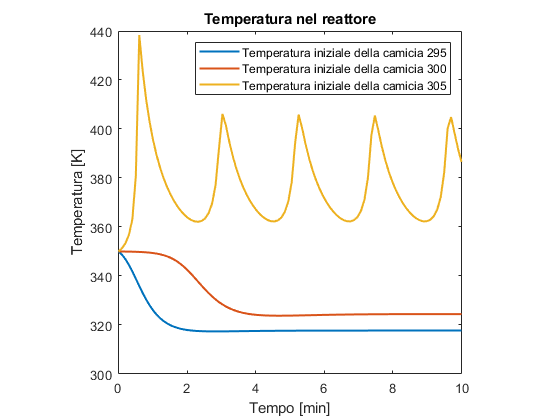

    figure(1)
    plot(t,sol(:,2)),hold on
    xlabel('Tempo [min]')
    ylabel('Temperatura [K]')
    title('Temperatura nel reattore')
    legT(IndexLeg) = {sprintf('Temperatura iniziale della camicia %3.0f',T_c)};
    legend(legT,'Location','northeast')

    drawnow

#### Grafico Concentrazione

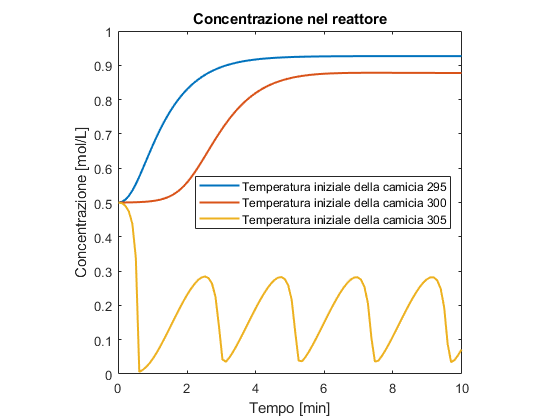

    figure(2)
    plot(t,sol(:,1)),hold on
    title('Concentrazione nel reattore')
    xlabel('Tempo [min]')
    ylabel('Concentrazione [mol/L]')
    legC(IndexLeg) = {sprintf('Temperatura iniziale della camicia %3.0f',T_c)};
    legend(legC,'Location','east')

drawnow
IndexLeg = IndexLeg + 1;
end

## Soluzione spazio ODES

Per capire quali sono le condizioni di Stabilità del sistema occorre andare ad analizzare il grafico delle variazioni di T e c, per capire in che condizioni queste sono entrambe nulle.

#### Valore camicia esterna nel reattore

T_c = 310;                 %Temperatura camicia attorno al mantello [K]

#### Grafico

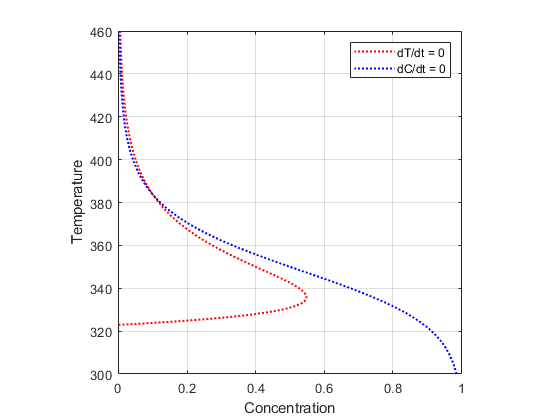

    clf(figure(3))
    figure(3)
    T = linspace(300.0,460.0,1000);
    EBnull = ((q/V).*(T_i-T) + (UA/V/rho/Cp).*(T_c-T))./((DeltaHR/rho/Cp)*k_0*exp(-Eatt/R./T));
    MBnull = (q/V)*c_Ai./((q/V) + k_0*exp(-Eatt/R./T));
    plot(EBnull, T, 'r:'),hold on
    plot(MBnull, T, 'b:')
    axis([0 1 300 460])
    grid on
    legend('dT/dt = 0','dC/dt = 0')
    xlabel('Concentration')
    ylabel('Temperature')    

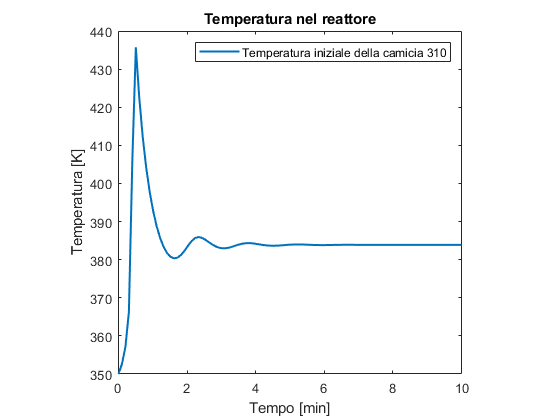

    x0 = [c_A0, T_0];
    tspan = linspace(0,10,100);
    options = odeset("RelTol",1e-6);
    [t,sol] = ode15s(@BMEB,tspan,x0,options,q,c_Ai,T_i,V,rho,Cp,DeltaHR,Eatt,k_0,UA,T_c,R);
    clf(figure(4))
    figure(4)
    plot(t,sol(:,2)),hold on
    xlabel('Tempo [min]')
    ylabel('Temperatura [K]')
    title('Temperatura nel reattore')
    legT2 = {sprintf('Temperatura iniziale della camicia %3.0f',T_c)};
    legend(legT2,'Location','northeast')

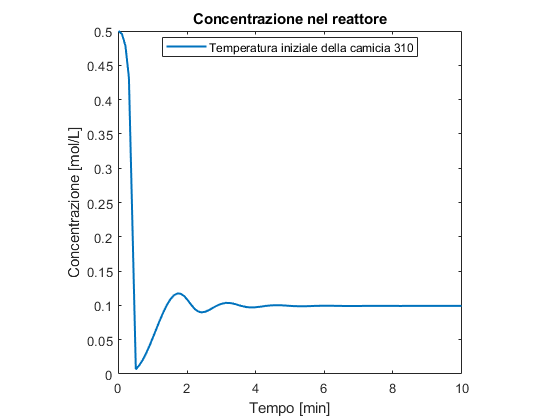

    clf(figure(5))
    figure(5)
    plot(t,sol(:,1)),hold on
    title('Concentrazione nel reattore')
    xlabel('Tempo [min]')
    ylabel('Concentrazione [mol/L]')
    legC2 = {sprintf('Temperatura iniziale della camicia %3.0f',T_c)};
    legend(legC2,'Location','best')

Andando ad analizzare l'andamento delle isocline di valore nullo, cioè del luogo dei punti in cui i valori delle derivate prime nel caso in esame sono nulli.

Possiamo notare che il sistema sarà allo stato stazionario solamente nei punti di intersezione tra le due linee.

Nel grafico sono riportate rispettivamente in rosso i valori dell'isoclina per il bilancio di energia, mentre il blu quelli dell'isoclina per il bilancio di materia della specie A all'interno della reazione.

### Definizione function per il calcolo con odes15

Per poter calcolare i risulatati delle funzioni occorre rielaborare le equazioni considerate in precedenza ottenendo:

Bilancio di materia per la specie A


$$\frac{dc_A}{dt}=\frac{q}{V}(c_{A,in} -c_{A})-kc_A$$


Bilancio di energia nel reattore


$$\frac{dT}{dt}=\frac{q}{V}(T_i-T)+\frac{(-\Delta H_{R})}{\rho C}kc_A+\frac{UA}{V\rho C}(T_c -T)$$


function [ddt] = BMEB(t,x0,q,c_Ai,T_i,V,rho,Cp,DeltaHR,Eatt,k_0,UA,T_c,R)
c_A = x0(1);
T = x0(2);
k = k_0*exp(-Eatt/R/T);
%Bilnacio di materia specie A
dcadt = q/V *(c_Ai - c_A) - k*c_A;
%Bilancio di energia
dTdt =q/V*(T_i - T) - DeltaHR/(rho*Cp)*k*c_A + UA/(V*rho*Cp)*(T_c - T);
ddt = [dcadt dTdt]';
end
